# Task 3

# Joint  trajectory 

q1=(0,0,0)  to q2=(2,3,4)

Controller command interpretation frequency "f = 100 Hz"

"Maximum joint velocity –1 rad/s"

"Maximum joint acceleration –10rad/s^2"

type = PTP (trapezoidal)

clear
% first joint condition
q0 = [0 0 0]

q0 =      0     0     0


% final joint condition 
qf = [2 3 4]

qf =      2     3     4


% Max joint velocities
v_max = [1 1 1];
% Max joint accuracy
a_max = [10 10 10];

% Ta is constant across the 3 joints
Ta = v_max(1)/a_max(1)

Ta = 0.1000

% delta q of the 3 joints
delta_q = [qf(:)-q0(:)]

delta_q =      2
     3
     4


% Tf changes throught  the 3 joints
Tf = [(abs(delta_q(:))/v_max(1))+Ta]

Tf =     2.1000
    3.1000
    4.1000


%deltaT = 100 hz
deltaT = 1/100;

% Because  Tf  are divisible by the deltaT 
% we don't have to  compute the  new time
% We need to make the 3 joints  arrive at the same exact  time ,
% so we choose the longest time tf = 4.1
Tfinal_new = 4.1; % new final time 
velocity_new = (delta_q(:))/(Tfinal_new - Ta) %new velocity

velocity_new =     0.5000
    0.7500
    1.0000


acceleration_new = velocity_new/Ta %new accuracy

acceleration_new =     5.0000
    7.5000
   10.0000


b = zeros(3,8);
for Joints = 1:3
    % t0 --> ta:
    a10 = q0(Joints);
    a11 = 0;
    a12 = 0.5*acceleration_new(Joints);
    
    
    % ta --> tf-ta:
    a20 = q0(Joints) + 0.5*acceleration_new(Joints).*Ta.^2 - velocity_new(Joints).*Ta;
    a21 = velocity_new(Joints);
    
    % tf-ta --> tf:
    a30 = qf(Joints) - 0.5*acceleration_new(Joints).*Tfinal_new.^2;
    a31 = acceleration_new(Joints).*Tfinal_new;
    a32 = -0.5*acceleration_new(Joints);
    b(Joints,:) = [a10; a11; a12; a20; a21; a30; a31; a32];%assign the results to the coeffs
end
b

b =          0         0    2.5000   -0.0250    0.5000  -40.0250   20.5000   -2.5000
         0         0    3.7500   -0.0375    0.7500  -60.0375   30.7500   -3.7500
         0         0    5.0000   -0.0500    1.0000  -80.0500   41.0000   -5.0000


time = (0:deltaT:Tfinal_new);

time =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


q_position = zeros(3,length(time));
q_velocity = zeros(3,length(time));
q_acceleration = zeros(3,length(time));
for Joints = 1:3
    q_position(Joints,:) = (b(Joints,1) +b(Joints,2).*time + b(Joints,3).*time.^2).*(time<=Ta)...
            +(b(Joints,4) +b(Joints,5).*time ).*(Ta < time).*(time <= (Tfinal_new-Ta))...
            +(b(Joints,6) +b(Joints,7).*time + b(Joints,8).*time.^2).*...
            ((Tfinal_new-Ta)<time).*(time <= Tfinal_new);
    q_velocity(Joints,:) = (b(Joints,2)+ 2*b(Joints,3).*time).*(time<=Ta)...
        + b(Joints,5).*(Ta < time).*(time <= (Tfinal_new-Ta))...
        +(b(Joints,7)+ 2*b(Joints,8).*time).*((Tfinal_new-Ta)<time).*(time <= Tfinal_new);
    q_acceleration(Joints,:) = 2*b(Joints,3).*(time<=Ta)...
        + 0.*(Ta < time).*(time <= (Tfinal_new-Ta)) ...
        + 2*b(Joints,8).*((Tfinal_new-Ta)<time).*(time <= Tfinal_new);
end

# Plotting of the joint positions, velocities, acceleration

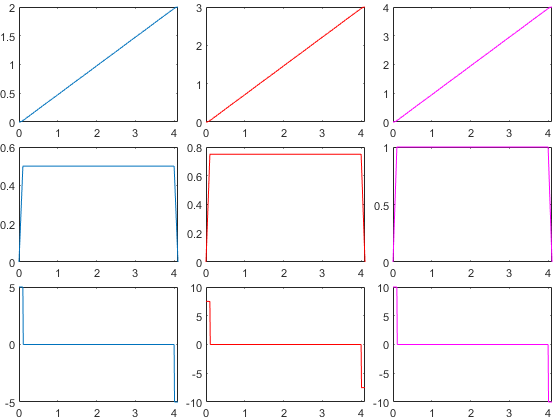

plt_2 = tiledlayout(3,3); % Requires R2019b or later
nexttile
plot(time,q_position(1,:),'DisplayName','q1_pos')
nexttile
plot(time,q_position(2,:),'r','DisplayName','q2_pos')
nexttile
plot(time,q_position(3,:),'m','DisplayName','q3_pos')
nexttile
plot(time,q_velocity(1,:),'DisplayName','q1_vel')
nexttile
plot(time,q_velocity(2,:),'r','DisplayName','q2_vel')
nexttile
plot(time,q_velocity(3,:),'m','DisplayName','q3_vel')
nexttile
plot(time,q_acceleration(1,:),'DisplayName','q1_acc')
nexttile
plot(time,q_acceleration(2,:),'r','DisplayName','q2_acc')
nexttile
plot(time,q_acceleration(3,:),'m','DisplayName','q3_acc')
plt_2.Padding = 'none';
plt_2.TileSpacing = 'none'; 